In this demo, we set the flow velocity to be 6, where the pipe system is under flutter. We construct a 2D unstable SSM around the unstable straight configuration. We expect there exists a stable limit cycle on the SSM. Under the addition of external control input at the free end, we are concerned with 

[1] M. Li, H. Yan, L. Wang: Nonlinear model reduction for a cantilevered pipe conveying fluid: A system with asymmetric damping and stiffness matrices. MSSP. 2023. [https://doi.org/10.1016/j.ymssp.2022.109993](https://doi.org/10.1016/j.ymssp.2022.109993)

%simple

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}  & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}  \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

nmodes = 4;
fcload = 1;
flowspeed = 5;

[M, C, K, fnl, fExt, fphi, phimid] = buildModelsimple(nmodes,fcload,flowspeed,'first');%first在中点的挠度 

the first four eigenvalues for undamped system


lamd =   -9.9154 + 0.0000i
   9.9154 + 0.0000i
   0.0000 +26.3989i
   0.0000 -26.3989i


n = size(M,1);

Create dynamical system 

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',10,'Nmax',10,'notation','multiindex')
set(DS.Options,'RayleighDamping',false)
[V,D,W] = DS.linear_spectral_analysis();


 The first 8 nonzero eigenvalues are given as 
   1.0e+02 *

   0.0992 + 0.0000i
  -0.0078 + 0.2639i
  -0.0078 - 0.2639i
  -0.0391 + 0.7801i
  -0.0391 - 0.7801i
  -0.0991 + 0.0000i
  -0.1256 + 1.5538i
  -0.1256 - 1.5538i



phiend = zeros(n,1);
lamda  = zeros(n,1);
lamda(1)=1.8751040687119611664453082410782141625701117335311;
lamda(2)=4.6940911329741745764363917780198120493898967375458;
lamda(3)=7.8547574382376125648610085827645704578485419292300;
lamda(4)=10.995540734875466990667349107854702939612972774652;
lamda(5)=14.137168391046470580917046812551772068603076792975;
lamda(6)=17.278759532088236333543928414375822085934519635550;
lamda(7)=20.420352251041250994415811947947837046137288894544;
lamda(8)=23.561944901806443501520253240198075517031265990051;
for k=1:n
   x    = 0.5;
   phin = cos(lamda(k)*x)-cosh(lamda(k)*x)-(cos(lamda(k))+cosh(lamda(k)))/(sin(lamda(k))+sinh(lamda(k)))*...
        (sin(lamda(k)*x)-sinh(lamda(k)*x));%clamped-free
   %phiend(k) = phin;
   phiend(k) = phimid(k);
   
end
% disp at the mid
obsfun = @(x,mapx,nmodes) mapx*x(1:nmodes,:);
obs = @(x) obsfun(x,phiend',n);

### Transient response prediction

tf     = 30; 
nsteps = 6000;
stepps=nsteps/tf;

z1=[-0.0259316290437874;-7.28837089046583e-19;0.00232709203019038;2.74423999975882e-19;0;0;0;0];
z0=[0.0259316290437874;7.28837089046583e-19;-0.00232709203019038;-2.74423999975882e-19;0;0;0;0];
z2=[-9.47032825980396e-07;3.03001618499176e-23;-2.49443452540486e-08;-1.65031352454730e-24;0;0;0;0]

z2 = 1.0e-06 *

   -0.9470
    0.0000
   -0.0249
   -0.0000
         0
         0
         0
         0


z3=[9.47032825980396e-07;-3.03001618499176e-23;2.49443452540486e-08;1.65031352454730e-24;0;0;0;0]

z3 = 1.0e-06 *

    0.9470
   -0.0000
    0.0249
    0.0000
         0
         0
         0
         0


outdof = 1:2*n;
set(DS,'u',[]);
[tInt,zInt] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z0);

[tInt1,zInt1] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z1);
[tInt2,zInt2] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z2);
[tInt3,zInt3] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z3);


### Stablization via LQR control


cont   = struct();
cont.Q    = zeros(2*n);
cont.Rhat = 0.1*(phiend'*phiend);
cont.Mhat = 1e4*eye(2*n)*(phiend'*phiend); % 1e4

Bext     = phiend;
% epsilon  = 1e-3;
epsilon  = 1;
set(DS,'D',Bext,'epsilon',epsilon);
set(DS.Options, 'outDOF', outdof);

SSM Learn

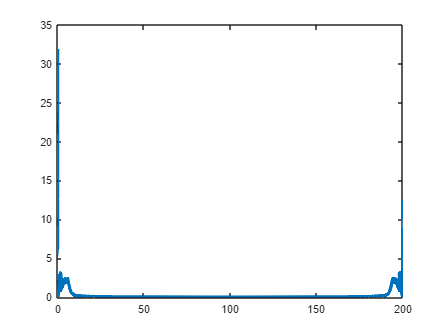

close all

useddim=[1];

starttime=6.3;
SSMstart=starttime*stepps;


NMTEmin=10000000000000;

xalldimwo=zInt(:,1:n)*phiend;
xalldimwo1=zInt1(:,1:n)*phiend;
xalldimwo2=zInt2(:,1:n)*phiend;
xalldimwo3=zInt3(:,1:n)*phiend;


Yfft=fft(xalldimwo);
plot(stepps/nsteps*(0:nsteps),abs(Yfft),"LineWidth",3)

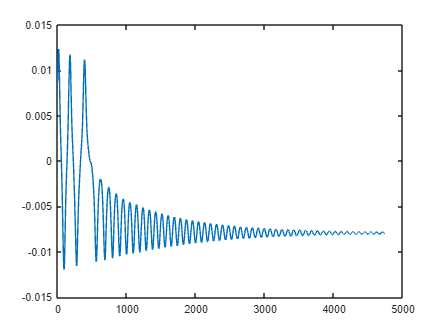




            xfullwoT=xalldimwo(SSMstart:end,useddim)';
            xfullwoT1=xalldimwo1(SSMstart:end,useddim)';
            xfullwoT2=xalldimwo2(SSMstart:end,useddim)';
            xfullwoT3=xalldimwo3(SSMstart:end,useddim)';
            plot(xfullwoT(1,:))

            lengthT=size(xfullwoT,2);
            tspan=linspace(0,lengthT/stepps,lengthT)

tspan =          0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2401    0.2451



            ydatac=cell(2,2);

            ydatac{1,1}=tspan;
            ydatac{1,2}=xfullwoT;
            ydatac{2,1}=tspan;
            ydatac{2,2}=xfullwoT1;
            ydatac{3,1}=tspan;
            ydatac{3,2}=xfullwoT2;
            ydatac{4,1}=tspan;
            ydatac{4,2}=xfullwoT3;
            SSMDim=2;
            overEmbed = 0;
            ydataembed = coordinatesEmbedding(ydatac, SSMDim, 'OverEmbedding', overEmbed);

The 5 embedding coordinates consist of the measured state and its 4 time-delayed measurements.



         
            SSMOrder =5

SSMOrder = 5


            [IMInfo, SSMChart, SSMFunction] = IMGeometry(ydataembed, SSMDim, SSMOrder);%ydata可以是nxN的矩阵（zauto）

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.476572e-12    1.315e-07    1.565e-17

初始点是满足约束的局部最小值。

优化已完成，因为在初始点处，目标函数沿可行方向在最优性容差值范围内呈现非递减，并且在约束容差值范围内满足约束。

<停止条件详细信息>


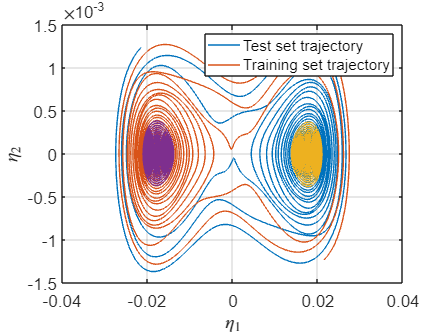


            yDataTrunc = sliceTrajectories(ydataembed, [0,20]);
            etaData = projectTrajectories(IMInfo, ydataembed);%Use the chart of a manifold to transform trajectories in the observable space to reduced coordinates on the manifold.


            plotReducedCoordinates(etaData);%fig3
            legend({'Test set trajectory', 'Training set trajectory'})

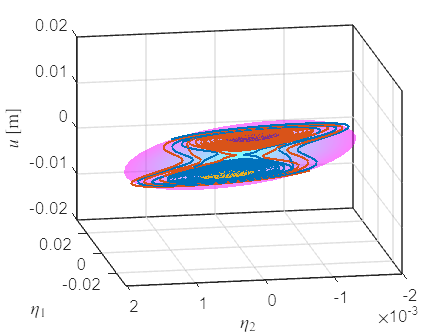



            plotSSMWithTrajectories(IMInfo, 1, ydataembed)%figure4 
            view(-100,20); zlabel('$u \, [$m$]$','Interpreter','latex')


                ROMOrder =15

ROMOrder = 15

                RDInfo = IMDynamicsFlow(etaData,  'R_PolyOrd', ROMOrder, 'style', 'normalform');

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
Normal form not available. Returning modal style.


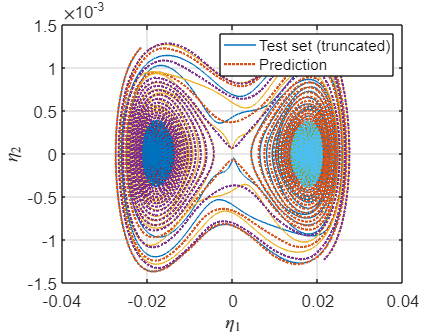

                %
                [yRec, etaRec, zRec] = advect(IMInfo, RDInfo, yDataTrunc);%通过流形 IMInfo 上 RDInfo 中的来advect yData 中的初始条件。？

                plotReducedCoordinates(etaData, etaRec)%测试和预测
                legend({'Test set (truncated)', 'Prediction'})

                %
                plotTrajectories(ydataembed([1 2],:), yRec([1 2],:), 'm', 'DisplayName', {'Test set', 'Prediction'})%fig7

fig =   Figure (5) - 属性:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  显示 所有属性


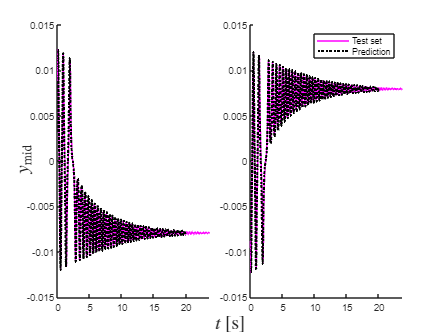

                 ylabel('$y_{\rm{mid}}$','Interpreter','latex','FontSize',18,'FontName','Times New Roman')
                 xlabel('$t \, [$s$]$','Interpreter','latex','FontSize',18,'FontName','Times New Roman')

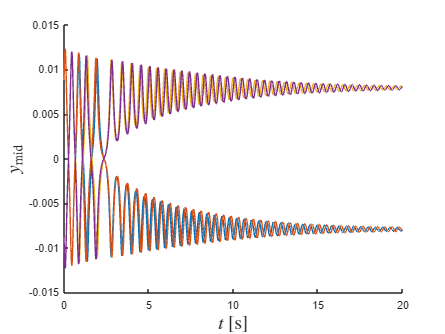


                 figure()
                 hold on
                 plot(ydataembed{1,1},ydataembed{1,2}(1,:))
                 plot(yRec{1,1},yRec{1,2}(1,:))
                 plot(ydataembed{2,1},ydataembed{2,2}(1,:))
                 plot(yRec{2,1},yRec{2,2}(1,:))
                 ylabel('$y_{\rm{mid}}$','Interpreter','latex','FontSize',18,'FontName','Times New Roman')
                 xlabel('$t \, [$s$]$','Interpreter','latex','FontSize',18,'FontName','Times New Roman')
                 xlim([0 20])

                normedTrajDist = computeTrajectoryErrors(yRec, ydataembed);
                NMTE = mean(normedTrajDist) % conjugacy error

NMTE = Inf

                if NMTE<NMTEmin
                    NMTEmin=NMTE;
                    iotm=i
                    jotm=j
                    kotm=k
                end



ztest=[9.47032825980396e-07;-3.03001618499176e-23;2.49443452540486e-08;1.65031352454730e-24;0;0;0;0]

ztest = 1.0e-06 *

    0.9470
   -0.0000
    0.0249
    0.0000
         0
         0
         0
         0


[tIntt,zIntt] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',ztest);
xalldimwotest=zIntt(:,1:n)*phiend;
xfullwoTest=xalldimwotest(SSMstart:end,useddim)';
ydatat{1,1}=tspan;
ydatat{1,2}=xfullwoTest;
ydataembedtest = coordinatesEmbedding(ydatat, SSMDim, 'OverEmbedding', overEmbed);

The 5 embedding coordinates consist of the measured state and its 4 time-delayed measurements.


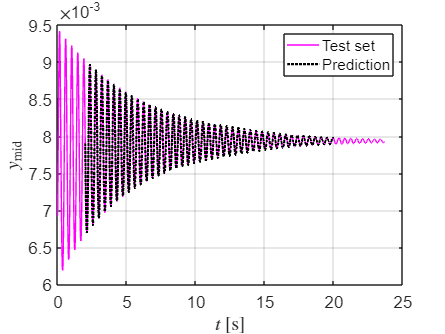

yDataTrunctest = sliceTrajectories(ydataembedtest, [2,20]);
[yRect, etaRec, zRec] = advect(IMInfo, RDInfo, yDataTrunctest);
plotTrajectories(ydataembedtest, yRect, 'm', 'DisplayName', {'Test set', 'Prediction'})%fig7
                ylabel('$y_{\rm{mid}}$','Interpreter','latex')
                xlabel('$t \, [$s$]$','Interpreter','latex')

MPC

load LSTMsimplenet.mat
load maxminout.mat
load maxminin.mat

TARGETy=0;
mpcsec=30;
mpciter=mpcsec*stepps

mpciter = 6000


predictsec=0.03;
T     = predictsec;  % control horizon
Np    = predictsec*stepps;  % number of control intervals

X0=0;

x0_last=0;

ufull=[];
udim=1;
uthres=2000;
DelR=0;

z0mpc=zInt(SSMstart+5,:);
z0mpcphiend=z0mpc(:,1:4)*phiend;
z0mpc7dim=ydataembed{1,2}(:,1);
zall=[z0mpcphiend];

Q  = 1e4*23;
R  = 0.1;

SSMfaultnum=0;

preally=[];
yu0=0;%predict(net,[0;0]);
yu0=double(yu0);


h=0.001

h = 1.0000e-03

u_guess=[-2*h,-h,h,2*h];
sim01=zeros(1,4);

for nodes=1:4
    hinput=[0;u_guess(nodes)];
    hinput01 = mapminmax('apply', hinput, ps_input);
    sim01(nodes)=predict(net,hinput01);
    sim = mapminmax('reverse', sim01, ps_output);
end

dxdu=(sim(1)-8*sim(2)+8*sim(3)-sim(4))/(12*h);

set(DS,'u',[])
[tIntwo,zIntwo] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z0mpc);
zallwo=zIntwo(:,1:n)*phiend;

for iter=1:mpciter

    advectmpc=cell(1,2);
    advectmpc{1,1}=tspan(:,1:Np);
    advectmpc{1,2}=repmat(z0mpc7dim,1,Np);
    [yRecmpc, etaRec, zRec] = advect(IMInfo, RDInfo, advectmpc);
    realSSMy=real(yRecmpc{1,2}(5,:));

    u=MPCu(Q,R,dxdu,SSMnexty,yu0,TARGETy)

    if u<- uthres
        u=-uthres;
    end
    if u>uthres
        u=uthres;
    end

    lstminput=[0;u];
    lstminput01 = mapminmax('apply', lstminput, ps_input);
    lstmPRE01=double(predict(net,lstminput01));
    lstmPRE = mapminmax('reverse', lstmPRE01, ps_output);

    prey=SSMnexty+lstmPRE;

    umpc_length=10;
    utrep=repmat(u,1,umpc_length);
    umpc_sec=umpc_length/stepps;
    tspan_umpc=linspace(0,umpc_sec,umpc_length);
    ommpc = 2*pi/umpc_sec;
    ufun = @(t) transpose(interp1(tspan_umpc,utrep,t));
    set(DS,'u',ufun)
    [t_umpc, xfullmpc,~,xalldimmpc] = time_integration_transient(DS,ommpc,'nCycles',...
        1, 'nSteps',umpc_length,...
        'integrationMethod','ode15s','outdof',outdof,'init',z0mpc);


    y0real2=xalldimmpc(2,1:n)*phiend;
    err= (prey-z0mpcphiend)/(y0real2-z0mpcphiend);

    ufull=[ufull,u];
    zall=[zall,z0mpcphiend];

    z0mpc=xalldimmpc(2,:);

    z0mpcphiend=z0mpc(:,1:n)*phiend;
    z0mpc7dim=[z0mpc7dim(2:end,:);z0mpcphiend];



    
    preally=[preally,prey];


end




figlength=size(zall,2)-1

figlength = 6000

figx=linspace(0,figlength/stepps,figlength)

figx =          0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


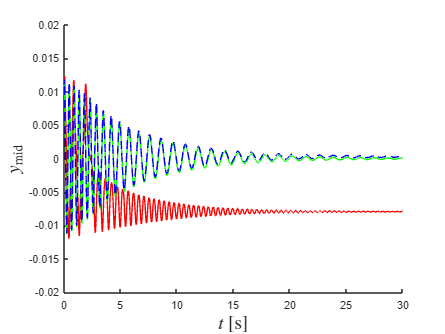

figure()
hold on
plot(figx,  zallwo(1:figlength,1),'r-','DisplayName', 'Full-without control');
plot(figx,  zall(1,1:figlength),'g-','DisplayName', 'Full-with control');
plot(figx, preally(1,1:figlength),'b--','DisplayName', 'pre Full-with control')
ylim([-0.02,0.02])
ylabel('$y_{\rm{mid}}$','Interpreter','latex','FontSize',18,'FontName','Times New Roman')
xlabel('$t \, [$s$]$','Interpreter','latex','FontSize',18,'FontName','Times New Roman')

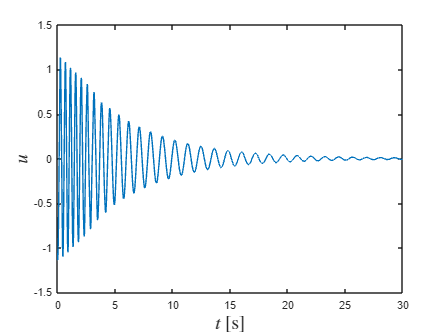

figure()
plot(figx(1:end),ufull)
ylabel('$u$','Interpreter','latex','FontSize',18,'FontName','Times New Roman')
xlabel('$t \, [$s$]$','Interpreter','latex','FontSize',18,'FontName','Times New Roman')

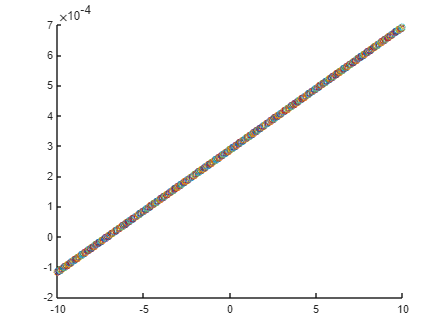

figure()
hold on
for u=-10:0.01:10
    predinput=[0;u];
    predinput01 = mapminmax('apply', predinput, ps_input);
    pred01=predict(net,predinput01);
    preddd = mapminmax('reverse',  pred01, ps_output);
    plot(u,preddd,'o')
end